# Neurotechnology, Brains and Machines: Week 2

Sam Michalka

Some of this should be attributed to *Statistics in MATLAB: A Primer* by MoonJung Cho and Wendy L. Martinez. Chapter 4 should be a reference for this notebook.

This notebook is not a stand-alone information source.  You will need to seek out external resources.

# Distributions and Plots

MATLAB allows us to create a distribution object, which we can then sample from to create a vector of random numbers. This probability distribution class is very useful... more on this later.  For now, we'll just focus on normal distributions.

**Exercise: Manipulate the value of n and numbins to get a sense of these two factors.**


distobj1 = makedist('Normal','mu',1,'sigma',2);
n = 5000; %Number of data points in sample
yval = distobj1.random(n,1); %Select a random sample from the distribution
histogram(yval); %If you don't set the number of bins, matlab chooses.
xlabel('Values'); ylabel('Frequency');
set(gca,'FontSize',14); % Set font size to make things prettier
% You can use histfit to create a histogram with a line fit to your distribution.
numbins = 30; %Number of bins in histogram 
histfit(yval,numbins,'Normal'); xlabel('Values'); ylabel('Frequency');

**Exercise: Why might we want to represent our data as a smooth distribution?**

% Answer text goes here

We can use the histogram function to plot the relative probability instead of the actual frequency.

histogram(yval,numbins,'Normalization','probability');
xlabel('Values'); ylabel('Relative Frequency');

# Probability density function (pdf)

We can use a probability density function to represent the shape of the distribution.

The result of evaluating a PDF for a particular value of x is not a probability; it is a probability density. The probability density measure probability per unit of x, so to get a probability mass, you have to integrate over x. 

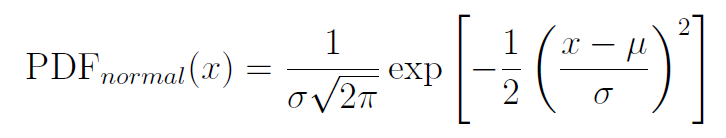

The probability density functions can be useful for comparing different distributions. 

X = -6:.1:8; %Set some values of x to evaluate at
distobj1 = makedist('Normal','mu',1,'sigma',2);
plot(X,distobj1.pdf(X),'LineWidth',2);


hold on;
distobj2 = makedist('Normal','mu',0,'sigma',2);
plot(X,distobj2.pdf(X),'LineWidth',2);
distobj3 = makedist('Normal','mu',1,'sigma',1);
plot(X,distobj3.pdf(X),'LineWidth',2);
xlabel('Values'); ylabel('PDF'); 
legend({'Normal, mu=1, sigma=2','Normal, mu=0, sigma =2','Normal, mu=1, sigma=1'});
hold off;

# Cumulative Distribution Function (cdf)

Like the pdf, the cdf can be called as a method for the distribution object.

You can see all available methods for an object by calling methods()

methods(distobj1)

**Exercise: Plot and label the cumulative distribution functions for the 3 distributions above.**

% Answer code goes here


**Exercise: Describe the effects of the mean and standard deviation on the cdf.**

% Answer text goes here

Now let's return to a single distribution, distobj1 (mu = 1, sigma =2). The methods for cdf and pdf take in numerical values and output the probability distribution value at the given numerical value.  You can confirm that these values at mean =1 correspond to the pdf and cdf plots.

distobj1.pdf(1)
distobj1.cdf(1)
distobj1.cdf(distobj1.mu)  % just another way of writing the line directly before this one

**Exercise: Look up the area under the curve of a normal distribution. Remember that the cdf outputs the area under the pdf for values up to and including the input value. Determine/Justify what value you should expect the cdf to output if the input value is 1 standard deviation below the mean. Then confirm by calling the cdf method.**

% Answer code (and text) goes here (or below)


**Exercise: Look up the area under the curve of a normal distribution. Determine/Justify what value you should expect the cdf to output if the input value is 1.96 standard deviations above the mean. Then confirm by calling the cdf method.**

% Answer code (and text) goes here (or below)


The inverse cumulative distribution function takes in a proportion (betwen 0 and 1), and outputs a value x such that the probability of X ≤ x is greater than or equal to p. This is illustrated as the area under the pdf between negative infinity and x. Remember that the cdf is the intergral of the pdf. 

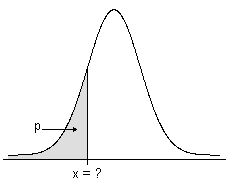

Let's think about an example. We know that distobj1 contains a normal distribution with a mean of 1 and a standard deviation of 2.  When x = the mean = 1, we expect p = 0.5. The area under the pdf curve to the left of x = 1 should be half (0.5) of the the total area under the curve (which is 1).  We can confirm this with the icdf method.

p = 0.5; %proportion of total area under the pdf curve for X<=x OR y-value of the cdf at x. 
distobj1.icdf(p)
distobj1.mu %This is the mean

**Exercise: Confirm your answer for the previous exercise (case of 1.96 stdevs above the mean). **

% Answer code goes here



**Exercise: Plot/Label the ****inverse**** cumulative distribution function. Consider what values are appropriate for the x-axis.**

% Answer code goes here.


# Standardized normal distribution

The standardized normal distribution (or z-distribution) is a normal distribution, where the mean is 0 and the standard deviation is 1.  Converting our measurements into a z-score can be useful for comparing information from two scales. Regardless of your thoughts on standardized testing (e.g., the SATs and the ACTs), they are great for examples of comparing scores from different distributions. 

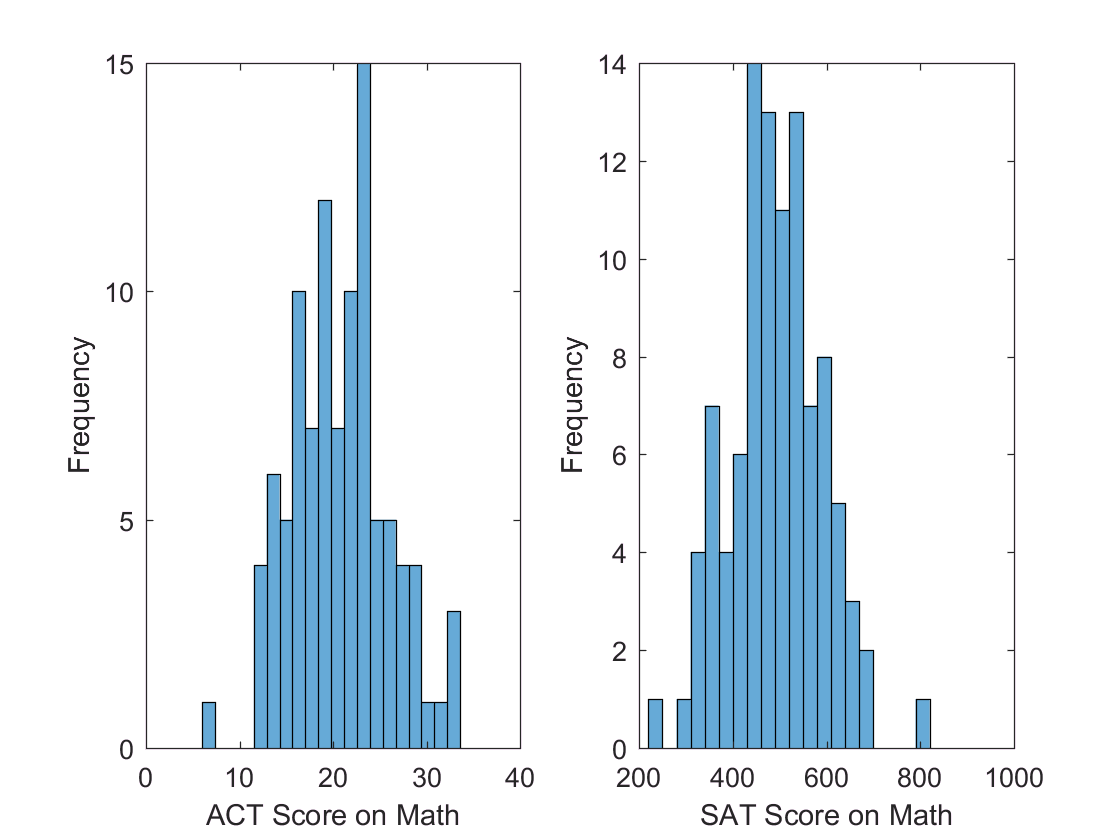

avals = normrnd(20.7,5.4,100,1); %Random values from ACT-like distribution (mean, stdev, num measurements, 1)
svals = normrnd(500,100,100,1); %Random values from SAT-like distribution (mean, stdev, num measurements, 1)
subplot(1,2,1); histogram(avals,20); xlabel('ACT Score on Math'); ylabel('Frequency')
subplot(1,2,2); histogram(svals,20); xlabel('SAT Score on Math'); ylabel('Frequency')

**Exercise: Convert each of the test scores to z-scores and plot them in their own subplot (just like above).**

% Answer code goes here

**Exercise: One ambitious student has decided to take the ACT and the SAT (just focusing on math). Now they are deciding which scores they want to report to get that sweet sweet college scholarship money. They scored a 34 on the ACT and a 720 on the SAT. Use z-scores to determine which test they did "better" on.  You can get the  means and standard deviations in the code above.**

%Answer code and text goes here

# Effect sizes

Read questions/sections 1, 2, 3, 4, and 7 of this paper: [http://www.cem.org/attachments/ebe/ESguide.pdf](http://www.cem.org/attachments/ebe/ESguide.pdf) about effect sizes.  We will talk more about statistical significance and hypothesis testing later, so don't worry about the details of those things (especially if this is new to you).

The following is an example looking at sex differences in person height and brain weight.

Reference: Witelson, S. F., Beresh, H., & Kigar, D. L. (2006). Intelligence and brain size in 100 postmortem brains: sex, lateralization  Jarrett, Christian. Great Myths of the Brain (Great Myths of Psychology) (p. 125). Wiley. Kindle Edition. 

Here, we'll only look at right-handed people (separated in study table). This is just a quick peek at a complex data set. There were many additional differences between these two groups  in addition to their sex.  

First, we will look at height, measured in inches. We will assume these are normal distributions.

% Right handed subjects from from Witelson et al.
nf = 38; % num female
nm = 20; % num male

% height in inches
hmeanf = 64; % height mean (females)
hmeanm = 69.3; % height mean (males)
hsdf = 3.2; %height stdev females
hsdm = 2.8; %height stdev males
hvals = 40:.2:100; % height range to look at (inches)
fheight = makedist('Normal','mu',hmeanf,'sigma',hsdf); % Normal distribution of right handed female heights
mheight = makedist('Normal','mu',hmeanm,'sigma',hsdm); % Normal distribution of right handed female heights

% Plot the distributions
plot(hvals,mheight.pdf(hvals),'b','LineWidth',2)
hold on
plot(hvals,fheight.pdf(hvals),'r','LineWidth',2);
legend({'Male','Female'}); xlabel('Height (in)'); ylabel('PDF');
hold off;

Note that the two groups have different standard deviations, which affects the shape and height of the pdf. To calculate effect sizes, we need to use a standard deviation. In some cases, it might make sense to use the standard deviation for one group or the other, but usually we need to find the pooled standard deviation between our two groups. The equation can be found here:

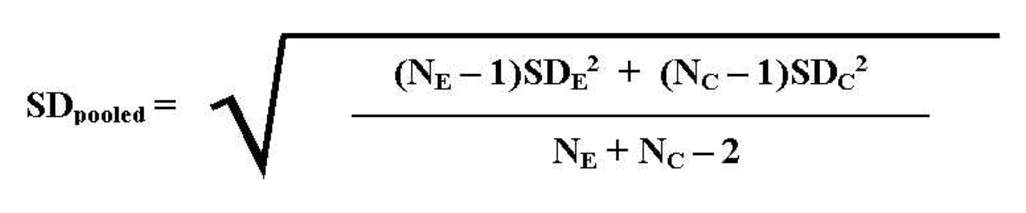

where SD is standard deviation, N is number of participants, E and C are the two groups (classically referred to as experimental and control, but the naming doesn't apply in our case).

% Calculate the pooled standard deviation for males & females
heightsdpooled = sqrt(((nm-1)*(hsdm.^2) + (nf-1)*(hsdf.^2))./(nf+nm-2))

Note that the pooled standard deviation is slightly closer to the standard deviation for females, as there are more females in the study.

% Calculate the effect size 
heightcohensd = (hmeanm-hmeanf)./heightsdpooled

Studies have consistently shown differences in brain mass between sexes, so we expect to find those differeneces here. Later on, we will read about how brain weight is not a good correlate of intelligence.

 The numbers in this study represent data from a small to medium sized sample, so these will only give a rough estimate of the effect size. We are going to plot distributions and evaluate effect sizes around whole brain weight differences, though there are many ways to weigh a brain.

% Fresh whole brain weight 
fbwmean = 1278; % mean female brain weight
mbwmean = 1373; % mean male brain weight
fbwsd = 103; %sd female
mbwsd = 102; % sd male
w = 700:1900; %Range of weights to look at
fbrainweight = makedist('Normal','mu',fbwmean,'sigma',fbwsd); % Normal distribution of right handed female brain weights 
mbrainweight = makedist('Normal','mu',mbwmean,'sigma',mbwsd); % Normal distribution of right handed male brain weights 

% Plot the distributions
plot(w,mbrainweight.pdf(w),'b','LineWidth',2)
hold on
plot(w,fbrainweight.pdf(w),'r','LineWidth',2);
legend({'Male','Female'}); xlabel('Brain Weight (g)'); ylabel('PDF');
hold off;

**Exercise: Calculate the pooled standard deviation of brain weights for males & females**

% Answer code goes here


**Exercise: Calculate the effe****ct size for the differences in brain weight.  Comment on how this compares to the effect size for height differences.**

% Answer code goes here


% Answer text goes here.

# Exploring distribution types

We spend a lot of time talking about normal distributions, but they are certainly not the only type of distribution. Table 4.1 in the Martinez & Cho Statistics in Matlab book lists several other continuous distributions that are easily accessible in Matlab.

One way to experiment with these distributions is to use disttool.  This funciton will show something in the notebook (that you can't click on), but will also pop out a GUI to experiment with. If you like GUIs, play around with the values and dropdown menus.  If you hate them, go ahead to the details below about how to script this.

disttool()

Just like with the normal distribution, we can create a distribution object for other distributions. Depending on the distribution, different parameters and methods may be available.

Let's use the exponential distribution as an example.  From Table 4.1 (or other online matlab/stats references), we know that the exponential distribution takes in one parameter: mu (the mean).   This is also a good resource: [https://www.mathworks.com/help/stats/pdf.html](https://www.mathworks.com/help/stats/pdf.html.) 

We will start by making a distribution object and choosing some values of x to evaluate over.

mydistobj = makedist('Exp','mu',2);
X = -0.5:.01:10;
plot(X,mydistobj.pdf(X));

We can also learn more about our new object by calling the methods function.

methods(mydistobj)

We can also type mydistobject. and then hit the tab button to see all of our methods and value options. (make sure to include the period)

mydistobj.median
mydistobj.var

We can select random variables from this distribution and assign them to a vector.

vals = mydistobj.random(6,1) % These values determine the vector size

**Exercise: **

**1) Select a new continuous distribution type, research the relevant parameters and describe how they affect the shape of the distribution. (You may want to do some of the other steps before you write this part).**

**2) Plot the pdf and cdf for your distribution over some range of values that fully captures the distribution.**

**3) Create a large vector (at least 100 values) of values that have been randomly selected from your distribution. Plot these in a histogram.**

**4) Find an example of this distribution in the real world. You don't need to find data for this part, just describe a situation where this distribution is used.**

**5) Repeat steps 1-4 for 2 other distributions.**